# R11521212 鄭傳嶧 HW10_1

clc;clear;close all;
opengl hardware; 

## read data

[data,txt,raw] = xlsread('Homework-2 data set-RCF-Four Specimen Test Data.xlsx');
dur = 4001:1:18001;
t = data(:,1);
sr = round(1/(t(2)-t(1)));  % sampling rate

## **define data, low pass, down-sample**

% case 1
RCF6_x = data(dur,3);
RCF6_y = data(dur,2);
relacc1 = RCF6_x - RCF6_y;
x1 = lowpass(relacc1,50,sr);
y1 = downsample(x1,4);
wpt1 = wpdec(y1,11,'db1');
% case 2
RCF4_x = data(dur,7);
RCF4_y = data(dur,6);
relacc2 = RCF4_x - RCF4_y;
x2 = lowpass(relacc1,50,sr);
y2 = downsample(x1,4);
wpt2 = wpdec(y2,11,'db1');

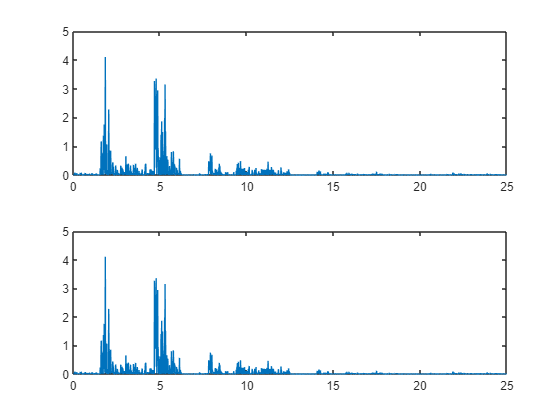

wpt = [wpt1 wpt2];
F=zeros(1,2^11);
E=zeros(2,2^11);
rcfs = zeros(2,3501);
for i = 1:2
    for j=1:1:(2^11)
        summation = 0;
        F(j)=(2*j-1)*25/(2^12);
        rcfs(i,:) = (wprcoef(wpt(:,i),[11,j-1]))';
        for k = 1:3501
            summation = summation + rcfs(i,k).^2;
        end
        E(i,j) = summation;
    end
end

for i = 1:2
    subplot(2,1,i)
    plot(F,E(i,:))
end